# 考察有没有可能对矩阵或向量用ode45操作

## 先进行一个标准操作

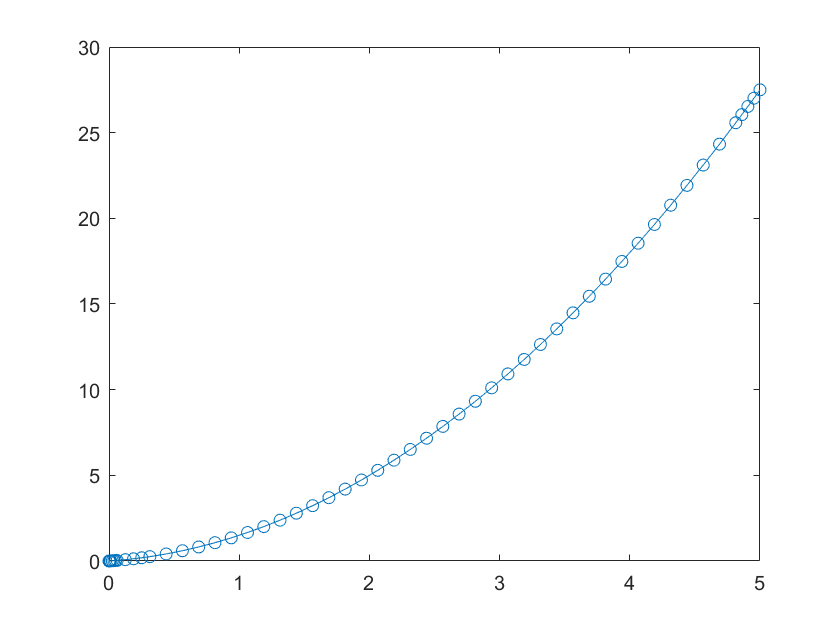

tspan = [0 5];
y0 = 0;
b=0.5;
[t,y] = ode45(@(t,y) 2*t+b, tspan, y0);

plot(t,y,'-o');


whos t y

  Name       Size            Bytes  Class     Attributes

  t         61x1               488  double              
  y         61x1               488  double              



## 假设y是一个有三个元素的向量

tspan = [0 5];
y0 = [0,0,-5]; y0=y0(:);
b = [0, 0.5, -0.5]; b=b(:);
[t,y] = ode45(@(t,y) myode(t,b), tspan, y0);

Inside myode
     0

         0
    0.5000
   -0.5000

         0
    0.5000
   -0.5000

Inside myode
   8.0380e-05

    0.0002
    0.5002
   -0.4998

         0
    0.5000
   -0.5000

Inside myode
   1.2057e-04

    0.0002
    0.5002
   -0.4998

         0
    0.5000
   -0.5000

Inside myode
   3.2152e-04

    0.0006
    0.5006
   -0.4994

         0
    0.5000
   -0.5000

Inside myode
   3.5725e-04

    0.0007
    0.5007
   -0.4993

         0
    0.5000
   -0.5000

Inside myode
   4.0190e-04

    0.0008
    0.5008
   -0.4992

         0
    0.5000
   -0.5000

Inside myode
   4.0190e-04

    0.0008
    0.5008
   -0.4992

         0
    0.5000
   -0.5000

Inside myode
   8.0380e-04

    0.0016
    0.5016
   -0.4984

         0
    0.5000
   -0.5000

Inside myode
    0.0010

    0.0020
    0.5020
   -0.4980

         0
    0.5000
   -0.5000

Inside myode
    0.0020

    0.0040
    0.5040
   -0.4960

         0
    0.5000
   -0.5000

Inside myode
    0.0022

    0.0044
    0.5044
   -0.

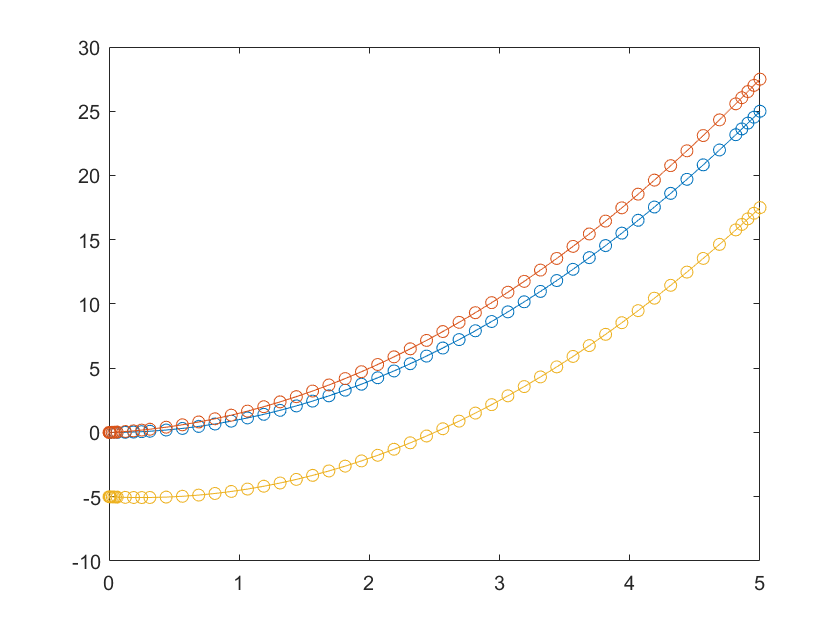


plot(t,y,'-o');


whos t y

  Name       Size            Bytes  Class     Attributes

  t         61x1               488  double              
  y         61x3              1464  double              



虽然在计算中，每一个时刻的y都是列向量，但是最终输出的结果，还是y的每一行有三个元素，每一行对应了一个特定的时刻t_n。

function y=myode(t,b)
    disp('Inside myode')
    y=2*t.*ones(3,1)+b;   % 程序要求返回列向量
    
    disp(t),disp(y),disp(b);
end